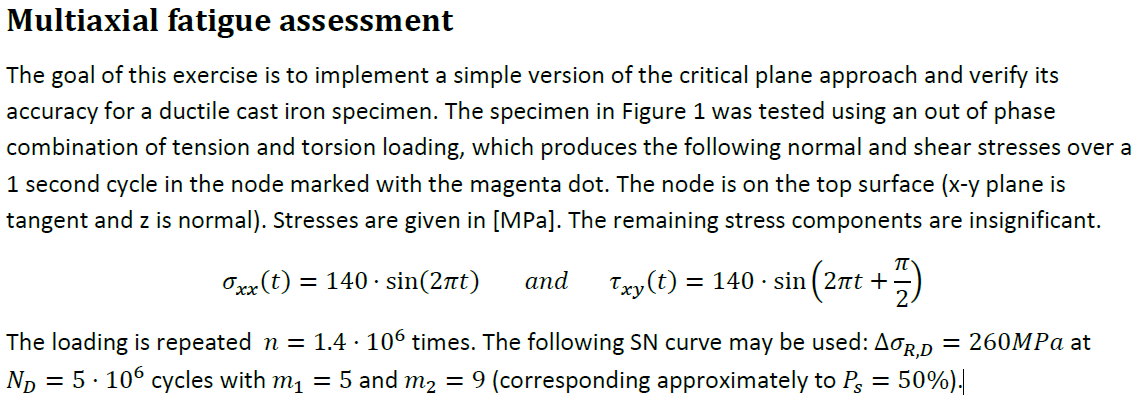

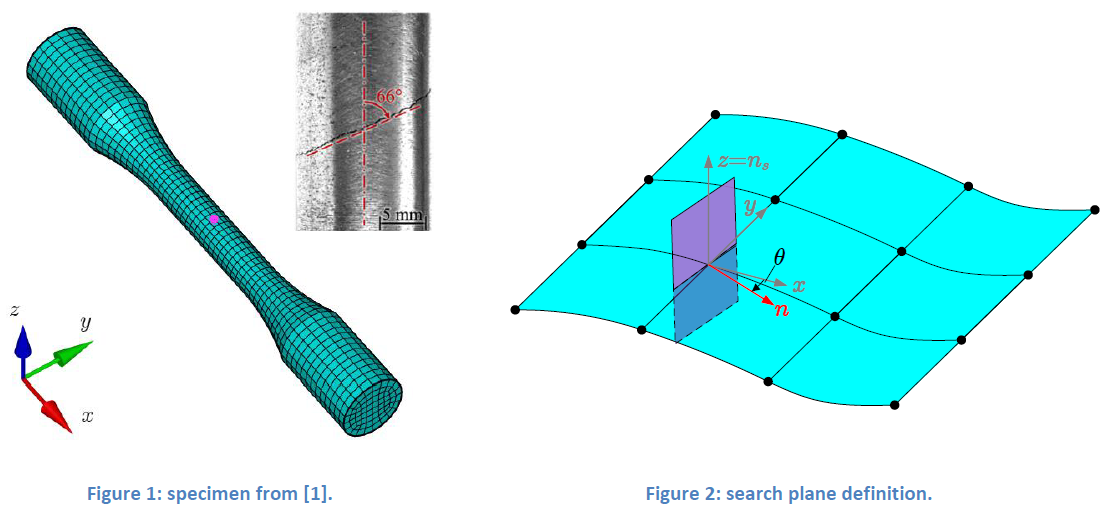

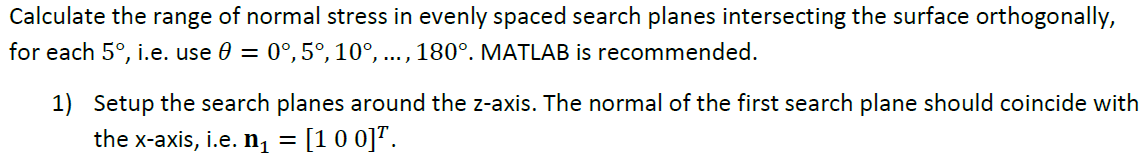

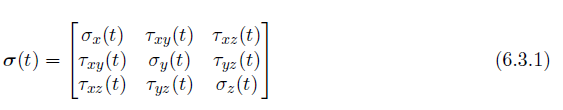

clear all
clf
deg = 5; %antal grader der skal roteres
theta = 0:deg:180-deg;
for i = 1:length(theta)
    n{i} = [cosd(theta(i)) sind(theta(i)) 0]';
end

t = 0:0.01:1;

for ti = 1:length(t)
    S_xx = 140 * sin(2*pi*t(ti));
    tau_xy = 140 * sin(2*pi*t(ti)+pi/2);
    S(:,:,ti) = [S_xx, tau_xy, 0
                tau_xy, 0, 0
                0, 0, 0];

    S_xx(ti) = 140 * sin(2*pi*t(ti));
    tau_xy(ti) = 140 * sin(2*pi*t(ti)+pi/2);
end

2) In each plane, calculate the normal stress over time and determine its range.

for i = 1:length(theta)
    for j= 1:length(t)
    S_n(j) = n{i}' * S(:,:,j) * n{i};
    end
    dS_n(i) = max(S_n) - min(S_n);
end

dS_n = 280

dS_n =   280.0000  282.0619


dS_n =   280.0000  282.0619  287.8592


dS_n =   280.0000  282.0619  287.8592  296.3750


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986  314.4859


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986  314.4859  305.8163


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986  314.4859  305.8163  296.3750


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986  314.4859  305.8163  296.3750  287.8592


dS_n =   280.0000  282.0619  287.8592  296.3750  305.8163  314.4859  320.6986  323.2984  320.8623  312.9607  298.9704  278.7020  252.2772  220.1907  182.9300  141.2469   96.1068   48.6591         0   48.6591   96.1068  141.2469  182.9300  220.1907  252.2772  278.7020  298.9704  312.9607  320.8623  323.2984  320.6986  314.4859  305.8163  296.3750  287.8592  282.0619


max(dS_n)

ans = 323.2984

3) Calculate and plot the damage in each search plane as a function of the angle 𝜃.

4) Determine the angle of the critical plane and compare it with that of the experiment (66°).

5) If time allows, try the same analysis in Fatlab. Input files can be download here:

https://sourceforge.net/projects/fatlab/files/benchmarks/Multiaxial%20fatigue.zip

The loads file Loads_out-of-phase.xlsx corresponds to this exercise. Use node 2979.